Load data & Set length.

load HSW_200701.mat
Hd = EEG_filter();
LEN = 350000;

Slice data.

fp1 = data(:, 2);
fp2 = data(:, 3);

slice_start = round((length(fp1)-LEN) / 2);
slice_end = slice_start + LEN;

fp1 = fp1(1 + slice_start:slice_end);
fp2 = fp2(1 + slice_start:slice_end);

x = 1:LEN;

Apply filter.

filt_fp1 = filtfilt(Hd.Numerator, 1, fp1);
filt_fp2 = filtfilt(Hd.Numerator, 1, fp2);

Draw graph.

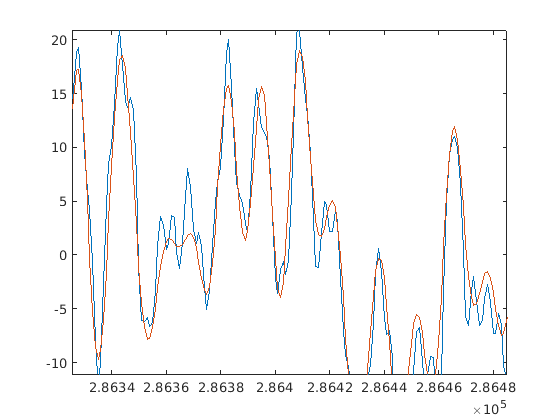

plot(x, fp1, x, filt_fp1);
xlim([288500 289000]);

Data cleansing.

data = [filt_fp1, filt_fp2];
clearvars filt_fp1 filt_fp2 fp1 fp2 Hd LEN slice_end slice_start x